# Lab - 08

format long e

### Question - 1

M = [10,20,30,40];
N = [10,20,30,40];

norm1 = [];
norm2 = [];
norm3 = [];
max_imag_eig_R = [];
min_eig_R = [];

for m = M
    for n = N
        A = randn(m,n);
        [W, R] = polard1(A);

        if m > n
            norm1 = [norm1, norm(W*R - A)];
            norm2 = [norm2, norm(W'*W - eye(n))];
        else
            norm1 = [norm1, norm(R*W - A)];
            norm2 = [norm2, norm(W*W' - eye(m))];
        end
        norm3 = [norm3, norm(R - R')];
        max_imag_eig_R = [max_imag_eig_R, max(imag(eig(R)))];
        min_eig_R = [min_eig_R, min(eig(R))];
    end
end

[norm1', norm2', norm3', max_imag_eig_R', min_eig_R']

ans =      1.056170383571356e-14     1.834625611725483e-15     5.977312544883146e-16                         0     1.777771408547198e-01
     1.675962735323416e-14     2.201254684157615e-15     4.932701965238063e-16                         0     1.491759041293468e+00
     1.405024984164879e-14     1.491396027635761e-15     8.449103908874033e-16                         0     2.674962432606450e+00
     2.022014974245793e-14     2.989920901641104e-15     8.239575384826692e-16                         0     3.705795155482813e+00
     1.839844103658847e-14     2.426940593269897e-15     8.793196771354023e-16                         0     1.540265079161678e+00
     4.326581809513845e-14     5.271190119168022e-15     7.971380692012620e-16                         0     3.463781439498325e-02
     9.035078733306796e-14     3.595920408572628e-15     9.584261789341274e-16                         0     1.320340654505623e+00
     5.283722573451977e-14     3.259590577542854e-15     1.250224955172280e-1

min(min_eig_R) % since this is non-negative, all values are non-negative

ans =      3.463781439498325e-02


It can be observed that A being an m x n matrix, if m >= n, A = WR else A = RW is giving all the values required as O(u) and the min(eig(R)) is non-negative for all the randomly generated matrices.

### Question - 2

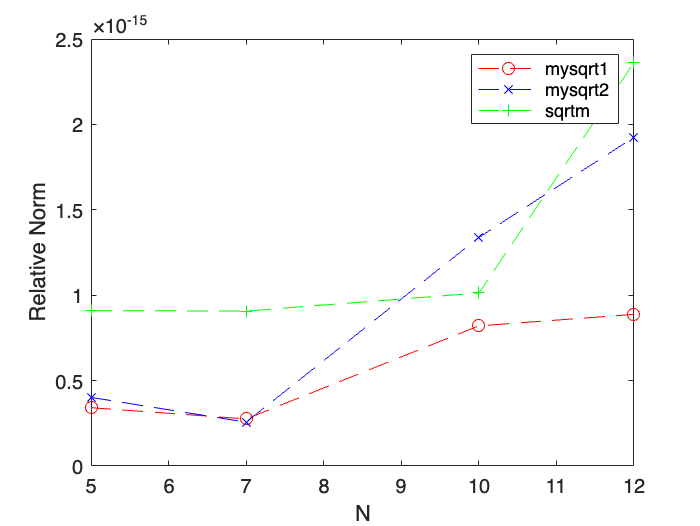

N = [5,7,10,12];
norm1_vals = [];
norm2_vals = [];
norm3_vals = [];

for n = N
    H = hilb(n);
    R1 = mysqrt1(H);
    R2 = mysqrt2(H);
    R3 = sqrtm(H);

    norm1_vals = [norm1_vals, norm(H - R1*R1) / norm(H)];
    norm2_vals = [norm2_vals, norm(H - R2*R2) / norm(H)];
    norm3_vals = [norm3_vals, norm(H - R3*R3) / norm(H)];
end

figure;
plot(N, norm1_vals, 'r--o');
hold on;
plot(N, norm2_vals, 'b--x');
hold on;
plot(N, norm3_vals, 'g--+');
xlabel('N');
ylabel('Relative Norm');
legend('mysqrt1', 'mysqrt2', 'sqrtm');
hold off;

From the plot, it can be observed that the function mysqrt1 is performing better than the other two in terms of the correctness of square root of different hilbert matrices, since the relative norm error is lowest for this function.

### Question - 3

M = [10,20,30,40];
N = [10,20,30,40];

norm1 = [];
norm2 = [];
norm3 = [];
max_imag_eig_R = [];
min_eig_R = [];

for m = M
    for n = N
        A = randn(m,n);
        [W, R] = polard2(A);

        if m > n
            norm1 = [norm1, norm(W*R - A)];
            norm2 = [norm2, norm(W'*W - eye(n))];
        else
            norm1 = [norm1, norm(R*W - A)];
            norm2 = [norm2, norm(W*W' - eye(m))];
        end
        norm3 = [norm3, norm(R - R')];
        max_imag_eig_R = [max_imag_eig_R, max(imag(eig(R)))];
        min_eig_R = [min_eig_R, min(eig(R))];
    end
end

[norm1', norm2', norm3', max_imag_eig_R', min_eig_R']

ans =      1.193317279361704e-15     1.444042124403064e-13     3.571884530801431e-15                         0     8.639083634586299e-02
     1.561610317451719e-15     2.975944157113551e-15     3.101297414484500e-15                         0     2.142653615742102e+00
     1.413163468875375e-15     2.520156312159696e-15     4.682534263512660e-15                         0     2.620275523028190e+00
     2.240767572340185e-15     2.948066347199375e-15     4.879174835614375e-15                         0     3.907082853145731e+00
     1.529684315857013e-15     2.185729008942013e-15     4.122859261263972e-15                         0     2.152229703867722e+00
     1.722125416503051e-15     2.737589982546343e-12     8.856626330830552e-15                         0     5.062102840526716e-02
     2.371871351987047e-15     1.737595059176933e-14     7.095401252625451e-15                         0     1.190042828761486e+00
     2.949074650947760e-15     5.022084723647006e-15     8.340102167469944e-1

min(min_eig_R) % since this is non-negative, all values are non-negative

ans =      5.062102840526716e-02


Here, for polard2 also, it can be observed that A being an m x n matrix, if m >= n, A = WR else A = RW is giving all the values required as O(u) and the min(eig(R)) is non-negative for all the randomly generated matrices.

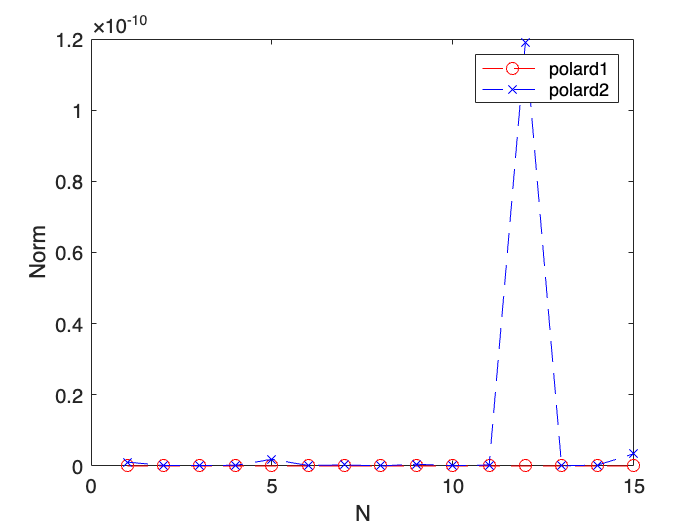

N = 1:15;
s_min_array = 10.^(6 - N);
norms1 = [];
norms2 = [];

for s_min = s_min_array
    Aj = generateAj(20, s_min);
    [Wj, Rj] = polard1(Aj);
    [Xj, Tj] = polard2(Aj);
    norms1 = [norms1, norm(Wj'*Wj - eye(20))];
    norms2 = [norms2, norm(Xj'*Xj - eye(20))];
end

figure;
plot(N, norms1, 'r--o');
hold on;
plot(N, norms2, 'b--x');
xlabel('N');
ylabel('Norm');
legend('polard1', 'polard2');
hold off;

After running the program for many times, it is observed that almost everytime the norm given by polard1 is more close to 0 (i.e. O(u)) than the norm given by polard2. 

The norm(Xj*Xj - I) is fluctuating randomly for different j (here j means minimum singular value of matrix is 10^(-j + 6) as stated in the question), sometimes it is almost same as norm(Wj*Wj - I), and sometimes it is significantly larger, i.e. order of 10^-10 to 10^-12. 

This shows that the polard1 method is better and more reliable than polard2 to compute the polar decomposition of a matrix.

### Question - 4

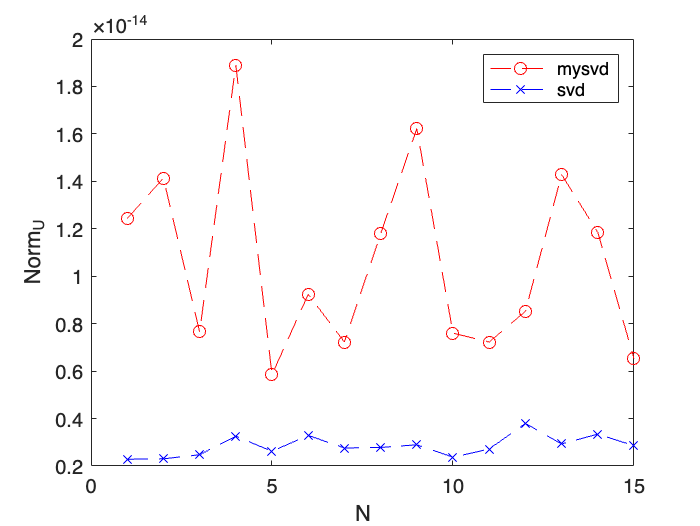

N = 1:15;
s_min_array = 10.^(6 - N);
norms_U1 = [];
norms_U2 = [];
norms_V1 = [];
norms_V2 = [];

for s_min = s_min_array
    Aj = generateAj(20, s_min);
    [U1, S1, V1] = mysvd(Aj);
    [U2, S2, V2] = svd(Aj);

    norms_U1 = [norms_U1, norm(U1'*U1 - eye(20))];
    norms_V1 = [norms_V1, norm(V1'*V1 - eye(20))];

    norms_U2 = [norms_U2, norm(U2'*U2 - eye(20))];
    norms_V2 = [norms_V2, norm(V2'*V2 - eye(20))];
end

figure;
plot(N, norms_U1, 'r--o');
hold on;
plot(N, norms_U2, 'b--x');
xlabel('N');
ylabel('Norm_U');
legend('mysvd', 'svd');
hold off;

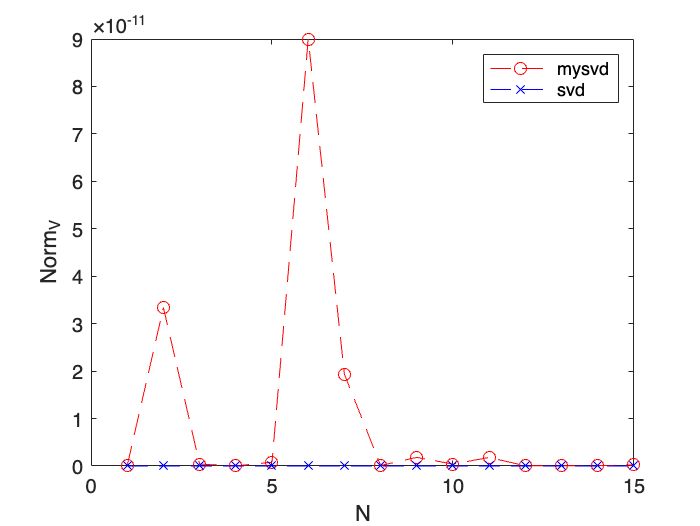


figure;
plot(N, norms_V1, 'r--o');
hold on;
plot(N, norms_V2, 'b--x');
xlabel('N');
ylabel('Norm_V');
legend('mysvd', 'svd');
hold off;

After running the program for many times, it is observed that almost everytime the norm given by svd is more close to 0 (i.e. O(u)) than the norm given by mysvd. 

The norm(Uj*Uj - I) and norm(Vj*Vj - I) given by mysvd are fluctuating randomly for different j (here j means minimum singular value of matrix is 10^(-j + 6) as stated in the question), sometimes they are almost same as norm(Uj*Uj - I) and norm(Vj*Vj - I) given by svd, and sometimes significantly larger, i.e. order of 10^-10 to 10^-12. 

This shows that the svd method is better and more reliable than mysvd to compute the svd of a matrix.

# Functions

function [W, R] = polard1(A)
    [m, n] = size(A);
    [U, S, V] = svd(A, "econ");
    
    W = U*V';
    if m > n
        R = V*S*V';
    else
        R = U*S*U';
    end
end

function R1 = mysqrt1(A)
    [X, D] = eig(A);
    if min(diag(D)) < 0
        error('Given matrix is not positive definite!');
    end
    D_sqrt = sqrt(diag(D));
    R1 = X * diag(D_sqrt) / X;
end

function R2 = mysqrt2(A)
    G = chol(A);
    [~,S,V] = svd(G);
    R2 = V*S*V';
end

function [W, R] = polard2(A)
    [m, n] = size(A);
    if m > n
        R = mysqrt1(A'*A);
        W = A / R;
    else
        R = mysqrt1(A*A');
        W = R \ A;
    end
end

function Aj = generateAj(n, s_min)
    Aj = randn(n);
    [U,S,V] = svd(Aj);

    sing_vals = diag(S);
    sing_vals = s_min * sing_vals / sing_vals(end);
    S = diag(sing_vals);

    Aj = U*S*V';
end

function [U,S,V] = mysvd(A)
    [m,n] = size(A);
    [W, R] = polard2(A);
    [X, D] = eig(R);
    % because R is self-adjoint, inv(R) = R'
    % so R = X*D*X'
    if m > n
        U = W*X;
        S = D;
        V = X;
    else
        U = X;
        S = D;
        V = W'*X;
    end
end